clc;
num=[1];
den=[10 2 5];
[A,B,C,D]=tf2ss(num,den);
k2=acker(A,B,[-4+i -4-i]);
sys_cl=ss(A-B*k2,B,C,D);
X=[2;0];
t=0:.1:10;
[y,t,x]=initial(sys_cl,X,t)

y =          0
    0.0134
    0.0179
    0.0178
    0.0157
    0.0130
    0.0102
    0.0078
    0.0058
    0.0043


t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


x =     2.0000         0
    0.7986    0.1338
    0.1666    0.1785
   -0.1366    0.1780
   -0.2571    0.1572
   -0.2815    0.1298
   -0.2600    0.1024
   -0.2204    0.0783
   -0.1771    0.0585
   -0.1373    0.0428


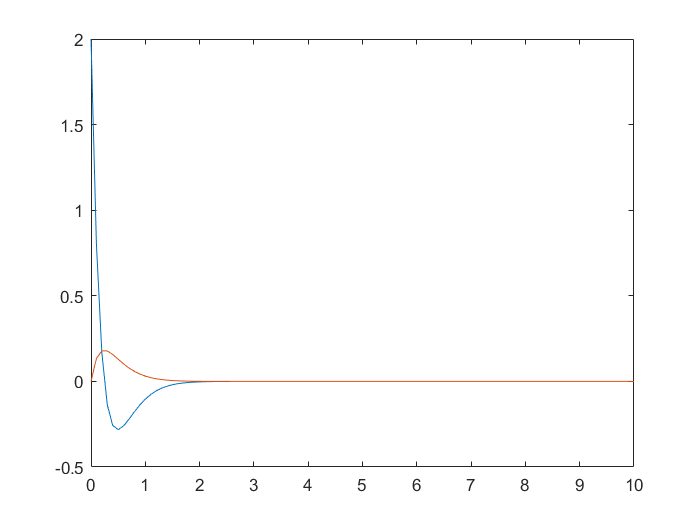

plot(t,x)